# Hellinger-Reissner Formulation for the Timoshenko Beam Boundary Value Problem

## Introduction

This chapter discusses the application of the Hellinger-Reissner principle for the one-dimensional Timoshenko beam problem using both the Penalty and the Lagrange Multipliers methods. The objective is to obtain a transverse-shear locking-free Finite Element formulation for the Timoshenko beam problem also when using low-order basis functions. The Boundary Value Problem (BVP) associated with the Timoshenko beam problem is detailed in the [introduction](matlab:open('../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) of [Chapter 1](matlab:open('../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')).

The standard weak formulation of the Timoshenko beam boundary value problem imposes strongly both subsidiary conditions regarding the constitutive equations and the kinematics in the principle of virtual work, namely,


$$\int_0^L \overbrace{\delta \left( \frac{\text{d} w}{\text{d} x} + \beta \right) \alpha G A \left( \frac{\text{d} w}{\text{d} x} + \beta \right)}^{\text{shear part of the stiffness}} + \overbrace{\delta \frac{\text{d} \beta}{\text{d} x} \, E I \, \frac{\text{d} \beta}{\text{d} x}}^{\text{bendingpart of the stiffness}} \; \text{d} x = \overbrace{\int_0^L \overline{q} \, \delta w + \overline{m} \, \delta \beta \; \text{d}x }^{\text{source loads}} + \overbrace{\left[ \delta w \, Q \right]_0^L + \left[ \delta \beta \, M \right]_0^L}^{\text{boundary loads}} \;. \quad (1)$$


The Hellinger-Reissner formulation of the problem does not impose the kinematics subsidiary condition strongly, but rather in a weak sense. The corresponding variational formulation of the Timoshenko beam problem using the Hellinger-Reissner principle reads as follows:


$$\int_0^L \delta \left( \frac{\text{d} w}{\text{d} x} + \beta \right) \, Q  \; \text{d} x - \delta Q \, \frac{1}{\alpha G A} \, Q + \delta Q \, \left( \frac{\text{d} w}{\text{d} x} + \beta \right) + \delta \frac{\text{d} \beta}{\text{d} x} \, M - \delta M \, \frac{1}{EI} \, M + \delta M \, \frac{\text{d} \beta}{\text{d} x} = \overbrace{\int_0^L \overline{q} \, \delta w + \overline{m} \, \delta \beta \; \text{d}x }^{\text{source loads}} + \overbrace{\left[ \delta w \, Q \right]_0^L + \left[ \delta \beta \, M \right]_0^L}^{\text{boundary loads}} \;. \quad (2)$$


where the unknown fields are the vertical deflection $w$, the cross-sectional deformation $\beta$, the reaction transverse shear forces $Q$ and the reaction bending moments $M$, respectively. As a matter of fact the reaction transverse shear forces $Q$ and the reaction bending moments $M$act as Lagrange Multipliers for the weak imposition of the kinematics subsidiary condition.

The example setup used herein for demonstration is the same one as in Chapter 1, see [here](matlab:open('../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')). This setup is a cantilever beam subject to vertical distributed load, see the following figure accordingly:

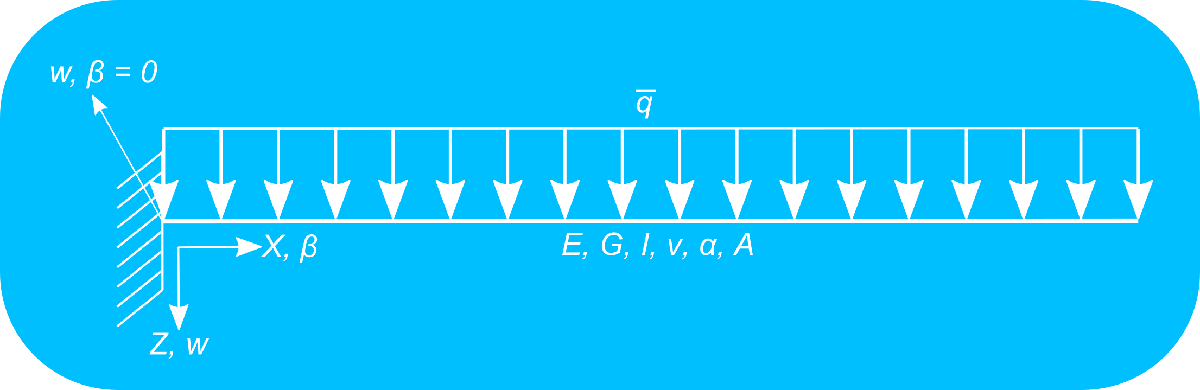

As a reference solution it herein used the solution derived in script [`main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx`](matlab:open('../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')) and highlighted [here](matlab:open('../2_TimoshenkoBeam/main_Chapter2_ALinearStraightTimoshenkoBeamElement.mlx')), since both setups are equivalent.

[PREVIOUS Chapter](matlab:open('../5_WeakDirichletBoundaryConditions/main_Chapter5_WeakBoundaryConditions_TimoshenkoBeam.mlx')) *Weak Imposition of Dirichlet Boundary Conditions for the Timoshenko Beam Boundary Value Problem*

[NEXT Chapter](matlab:open('./main_Chapter6_HellingerReissnerFormulation_TimoshenkoBeam_Study.mlx')) *Hellinger-Reissner Formulation for the Timoshenko Beam Boundary Value Problem - A Study*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem parameters**

### Geometric parameters

Thickness [m]

propStr.t = 10^(-2);

Width [m]

propStr.b = .1;

Height [m^2]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Material paramerters

Distributed load along the beam's length [N/m^2]

propStr.qBar = -1e4*(propStr.t)^3;

Distributed moment along the beam's length [N/m]

propStr.mBar = 0;

Boundary force [N]

propStr.Q = 0;

Boundary moment [Nm]

propStr.M = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Definition of the analytical solution

Initialization of the individual constituents

syms wEx(X) betaEx(X) QEx(X) Lsym qsym Gsym ...
    Aqsym Esym Isym alphaScf Acs

### Analytical solution with respect to the vertical deflection

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

### Derivation of the analytical solution with respect to the transverse-shear forces

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{Q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.A)*propStr.qBar - ...
    diff(diff(wEx, X), X));

### Evaluation of the expressions for the given geometric and material parameters

QEx(X) = alphaScf*Gsym*Acs*(diff(wEx(X), X, 1) + betaEx(X));

### Evaluation of the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, propStr.alpha*propStr.b*propStr.t});
betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, propStr.alpha*propStr.b*propStr.t});
QEx(X) = subs(QEx, {alphaScf, Gsym, Acs, Lsym, qsym, Gsym, Esym, ...
    Isym, Aqsym}, {propStr.alpha, propStr.G, propStr.A,XL, ...
    propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});

## Definition of the basis functions for the primal field interpolation - Vertical deflection and cross-sectional rotation field

### Definiion of the analytical expressions for the linear basis functions of the primal field interpolation


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{1-\xi }{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{1+\xi }{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 2\right)
\end{array}$$


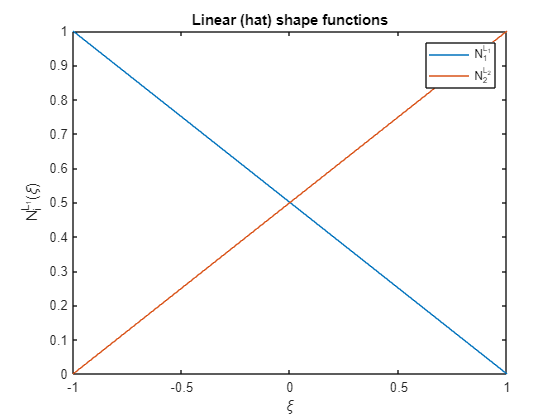

syms Nu1L1(xi) Nu2L1(xi) NuL1(xi)
Nu1L1(xi) = 1/2*(1 - xi);
Nu2L1(xi) = 1/2*(1 + xi);
NuL1(xi) = [Nu1L1(xi) Nu2L1(xi)];
h1 = fplot(NuL1, [-1 1]);
xlabel("\xi");
ylabel("N_i^{L_1}(\xi)")
legend("N_1^{L_1}", "N_2^{L_2}");
title("Linear (hat) shape functions")

### Definiion of the analytical expressions for the quadratic basis functions of the primal field interpolation


$$\begin{array}{l}
N_1 \left(\xi \right)=\frac{\xi \;\left(\xi -1\right)}{2},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 1\right)\\
N_2 \left(\xi \right)=\frac{\xi \;\left(\xi +1\right)}{2}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 2\right)\\
N_3 \left(\xi \right)=-\left(\xi -1\right)\;\;\left(\xi +1\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\ldotp 3\right)
\end{array}$$


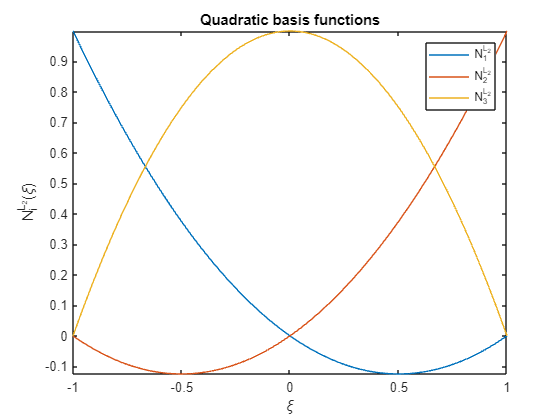

syms Nu1L2(xi) Nu2L2(xi) Nu3L2(xi) NuL2(xi)
Nu1L2(xi) = (xi*(xi - 1))/2;
Nu2L2(xi) = -(xi - 1)*(xi + 1);
Nu3L2(xi) = (xi*(xi + 1))/2;
NuL2(xi) = [Nu1L2(xi) Nu3L2(xi) Nu2L2(xi)];
h2 = fplot(NuL2, [-1 1]);
xlabel("\xi");
ylabel("N_i^{L_2}(\xi)")
legend("N_1^{L_2}", "N_2^{L_2}", "N_3^{L_2}");
title("Quadratic basis functions")

## Definition of the basis functions for the secondary field interpolation - Lagrange Multipliers

## Choice of the shape functions for the discretization of the Lagrange Multipliers

  **Try**

Change the value of parameter choice_shapeFunctions_LM to obtain either a constant, a linear or a quadratic Finite Element representation of the Lagrange Multipliers field, namely, the force/moment fields

choiceShapeFunctionsLM = 0

choiceShapeFunctionsLM = 0

syms Nbeta(xi)
switch choiceShapeFunctionsLM
    case 0

Constant shape functions


$$N_1 \left(\xi \right)=1,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(8\right)$$


    syms Nbeta1L0(xi)
    Nbeta1L0(xi) = 1;
    Nbeta(xi) = [Nbeta1L0(xi)];
    txt = 'Constant';

    case 1

Linear (hat) shape functions see Eq (6)

        Nbeta(xi) = [Nu1L1(xi) Nu2L1(xi)];
        txt = 'Linear';

    case 2

Quadratic shape functions, see Eq (7)

        Nbeta(xi) = [Nu1L2(xi) Nu2L2(xi) Nu3L2(xi)];
        txt = 'Quadratic';

    otherwise
        error("Variable 'choice_shapeFunctions_LM' can only take values 0 " + ...
            "(constant shape functions), 1 (linear shape functions) " + ...
            "or 2 (quadratic shape functions) but it has instead value %d", ...
            choiceShapeFunctionsLM);
end

disp(txt + " basis functions are chosen for the discretization of " + ...
    "the Lagrange Multipliers fields")

Constant basis functions are chosen for the discretization of the Lagrange Multipliers fields


### Visualization of the shape functions chosen for the secondary field interpolation

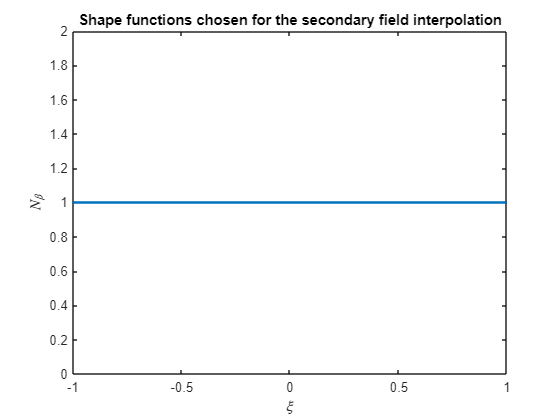

fplot(Nbeta, [-1 1], LineWidth=2);
xlabel("$\xi$", Interpreter="latex");
ylabel("$N_\beta$", Interpreter="latex");
title("Shape functions chosen for the secondary field interpolation")

## Discretization

The vertical deflection and rotation fields are discretized using the shape shape functions $N_i^u \;\left(\xi \right)$. Similarly, both the reaction transverse-shear forces and reaction bending moments are discretized using the same shape functions $N_i^{\beta } \;\left(\xi \right)$. Note, that the shape function sets $N_i^u \;\left(\xi \right)$ and $N_i^{\beta } \;\left(\xi \right)$ do not have to be the same.


$$\begin{array}{l}
w\left(\xi \right)\approx \sum_{i=1:N} N_i^u \;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 1\right)\\
\beta \left(\xi \right)\approx \sum_{i=1:N} N_i^u \;\beta_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 2\right)\\
Q\left(\xi \right)\approx \sum_{i=1:N} N_i^{\beta } \;Q_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 3\right)\\
M\left(\xi \right)\approx \sum_{i=1:N} N_i^{\beta } \;M_i \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(5\ldotp 4\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### Generate and display the one-dimensional mesh using linear two-noded elements

#### Mesh generation

numEl = 14;
mshL1 = generateLinearMeshOnLine(X0, XL, numEl);
numNodesL1 = numel(mshL1.nodes(:, 1));
isMeshNonUniform = false;
if isMeshNonUniform
    dx = mshL1.nodes(2, 1) - mshL1.nodes(1, 1);
    for ii = 2:numel(mshL1.nodes(:, 1)) - 1
        mshL1.nodes(ii, 1) = mshL1.nodes(ii, 1) + (2.*rand(1, 1) -1)/5;
    end
end

#### Definition of the boundary conditions

numDOFsL1 = 2*numel(mshL1.nodes(:, 1));
freeDOFsL1 = 1:numDOFsL1;
homDOFsL1 = 1:2;
[~, idxL1] = ismember(homDOFsL1, freeDOFsL1);
freeDOFsL1(idxL1) = [];

#### Mesh plot

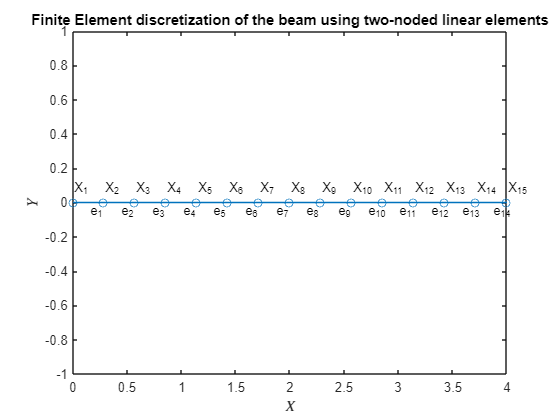

plotMesh1d(mshL1);
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "two-noded linear elements")

### Generate and display the one-dimensional mesh using quadratic three-noded elements

#### Mesh generation

mshL2 = generateQuadraticMeshOnLine(mshL1);
numNodes_L2 = numel(mshL2.nodes(:, 1));
isMeshNonUniform = false;
if isMeshNonUniform
    for ii = numel(mshL1.nodes(:, 1)) + 1:numel(mshL2.nodes(:, 1))
        mshL2.nodes(ii, 1) = mshL2.nodes(ii, 1) + (2.*rand(1, 1) -1)/5;
    end
end

#### Definition of the boundary conditions

numDOFsL2 = 2*numel(mshL2.nodes(:, 1));
freeDOFsL2 = 1:numDOFsL2;
homDOFsL2 = 1:2;
[~, idxL2] = ismember(homDOFsL2, freeDOFsL2);
freeDOFsL2(idxL2) = [];

#### Mesh plot

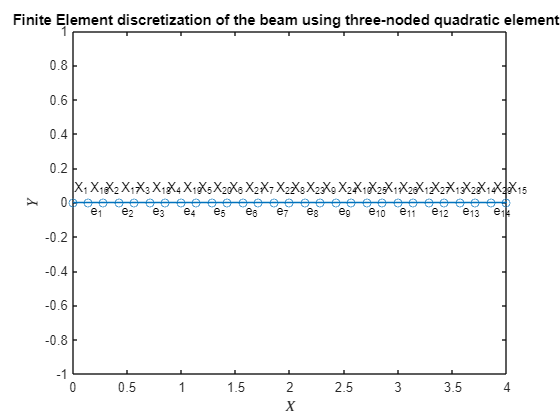

plotMesh1d(mshL2);
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "three-noded quadratic elements")

## **Master stiffness matrices and master consistent nodal force vectors**

### Linear finite elements and full integration

#### Computation of master stiffness matrix and load vector

computeStiffMatrixandForceVector = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL1, FL1Body] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVector, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### Computation of the** nodal force vector corresponding to boundary forces**

FL1Boundary = zeros(2*numNodesL1, 1);
FL1Boundary(end - 1, 1) = propStr.Q;
FL1Boundary(end, 1) = propStr.M;

#### Sum-up of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL1 = FL1Body + FL1Boundary;

#### Visualization of the sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

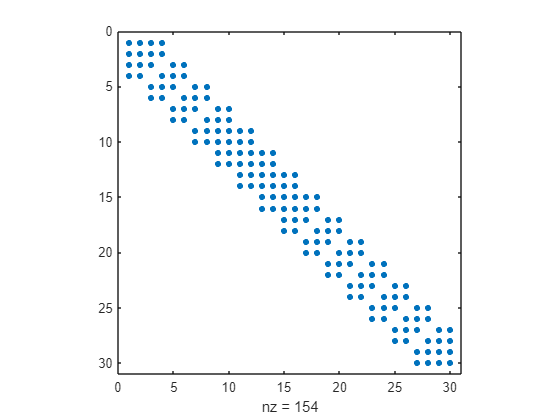

spy(KL1)

### **Quadratic finite elements and full integration**

#### Computation of master stiffness matrix and load vector

computeStiffMatrixandForceVector = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL2, FL2Body] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL2, computeStiffMatrixandForceVector, ...
    computeBasisFunctionsAndDerivs, dummyInp, propStr);

#### Computation of the** nodal force vector corresponding to boundary forces**

FBoundaryL2 = zeros(2*numNodes_L2, 1);
FBoundaryL2(2*numNodesL1 - 1, 1) = propStr.Q;
FBoundaryL2(2*numNodesL1, 1) = propStr.M;

#### Sum-up of the body-force vector corresponding to distributed loads and the body-force vector corresponding to boundary loads

FL2 = FL2Body + FBoundaryL2;

#### Visualization of the sparsity of the master stiffness matrix using linear finite elements corresponding to the full integration

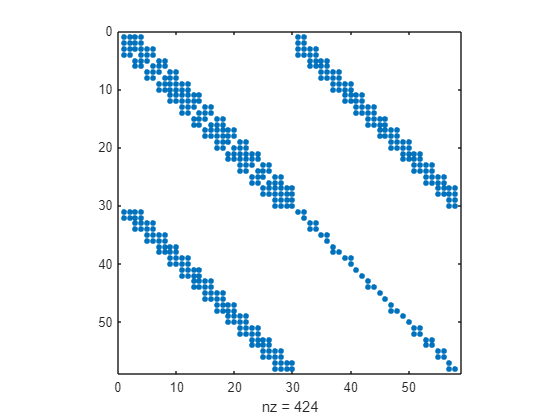

spy(KL2)

## Hellinger-Reissner formulation of the Timoshenko beam problem

### Initialize the global Hellinger-Reissner matrices and load vector

  **Try**

Change the value of variable `choice_shapeFunctions_u` to get a linear or a quadratic Finite Element representation of the unknown vertical deflection and cross-sectional rotation fields.

choiceShapeFunctionsU = 1;
switch choiceShapeFunctionsU

    case 1
        numDOFsHR = numDOFsL1;
        NuHR = NuL1;
        mshHR = mshL1;
        freeDOFsHR = freeDOFsL1;

    case 2
        numDOFsHR = numDOFsL2;
        NuHR = NuL2;
        mshHR = mshL2;
        freeDOFsHR = freeDOFsL2;

    otherwise
        error("Variable 'choice_shapeFunctions_u' can only take values " + ...
            "1 (linear shape functions), 2 (quadratic shape functions) " + ...
            "but it has instead value %d", choiceShapeFunctionsU);

end

KHR = zeros(numDOFsHR);
FHR = zeros(numDOFsHR, 1);

### Looping over all the elements in the mesh

for ii = 1:numel(mshL1.elements(:, 1))

#### Nodal indices and nodal coordinates

    id = mshHR.elements(ii, :);
    nodesElHR = mshHR.nodes(id);

#### Element stiffness matrix

    [Ke, Fe] = computeElStiffMtxForceVctHellingerReissnerTimoshenkoBeam ...
        (NuHR, Nbeta, nodesElHR, propStr);

#### Element Freedom Table (EFT)

    EFT = vertcat(2*id - 1, 2*id);
    EFT = EFT(:);

#### Assembly of the element contributions to the global HR matrices and load vector

    KHR(EFT, EFT) = KHR(EFT, EFT) + Ke;
    FHR(EFT) = FHR(EFT) + Fe;

end

### Sparsity pattern of the master stiffness matrix corresponding to the Hellinger-Reissner principle

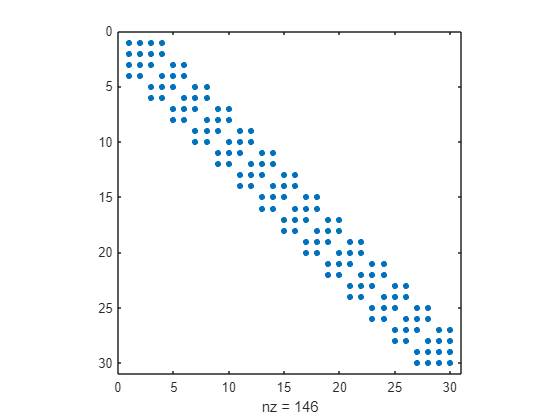

spy(KHR)

## Solution of the Timoshenko beam problem

### Linear finite elements

uL1 = zeros(numDOFsL1, 1);
uL1(freeDOFsL1) = KL1(freeDOFsL1, freeDOFsL1)\FL1(freeDOFsL1);

### Quadratic finite elements

uL2 = zeros(numDOFsL2, 1);
uL2(freeDOFsL2) = KL2(freeDOFsL2, freeDOFsL2)\FL2(freeDOFsL2);
[nodes_L2, idx] = sort(mshL2.nodes);
uL2Sorted = uL2(1:2:end, 1);
betaL2Sorted = uL2(2:2:end, 1);
uL2Sorted = uL2Sorted(idx);
betaL2Sorted = betaL2Sorted(idx);

### Hellinger-Reissner principle

#### Solution of the linear equation system and solution postprocessing

uHR = zeros(numDOFsHR, 1);
uHR(freeDOFsHR) = KHR(freeDOFsHR, freeDOFsHR)\FHR(freeDOFsHR);
if numDOFsHR == numDOFsL1
    nodesHR = mshHR.nodes;
    wHR = uHR(1:2:end, 1);
    betaHR = uHR(2:2:end, 1);
elseif numDOFsHR == numDOFsL2
    [nodesHR, idx] = sort(mshHR.nodes);
    uHRSorted = uHR(1:2:end, 1);
    betaHRSorted = uHR(2:2:end, 1);
    wHR = uHRSorted(idx);
    betaHR = betaHRSorted(idx);
end

#### Definition of the string indicating the discretization spaces for the Hellinger-Reissner formulation

if numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 0
    strHR = "L0-L1"
elseif numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 1
    strHR = "L1-L1";
elseif numDOFsHR == numDOFsL1 && choiceShapeFunctionsLM == 2
    strHR = "L2-L1";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 0
    strHR = "L0-L2";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 1
    strHR = "L1-L2";
elseif numDOFsHR == numDOFsL2 && choiceShapeFunctionsLM == 2
    strHR = "L2-L2";
else
    error("This combination of basis functions for the primal and " + ...
        "secondary unknown fields is not supported")
end

strHR = "L0-L1"

### Postprocessing the solution

#### Visualization of the deformed configuration

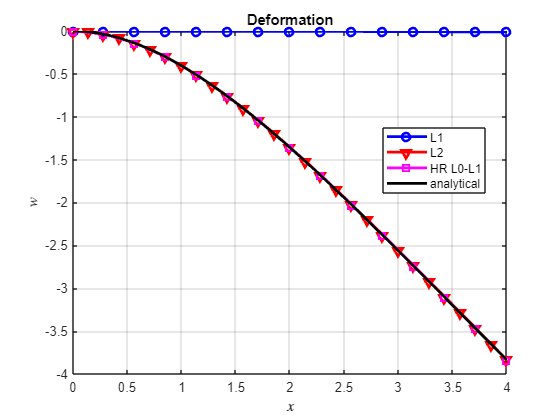

figure,
plot(mshL1.nodes, uL1(1:2:end, 1), '-bo', LineWidth=2);
hold on;
plot(nodes_L2, uL2Sorted, '-rv', LineWidth=2);
plot(nodesHR, wHR, '-ms', LineWidth=2);
fplot(wEx, [X0 XL], 'k-', LineWidth=2);
hold off;
grid on;
legend("L1", "L2", "HR " + strHR, "analytical", Location="best")
xlabel("$x$", Interpreter="latex");
ylabel("$w$", Interpreter="latex");
title("Deformation")

#### Visualization of the cross-sectional rotation field

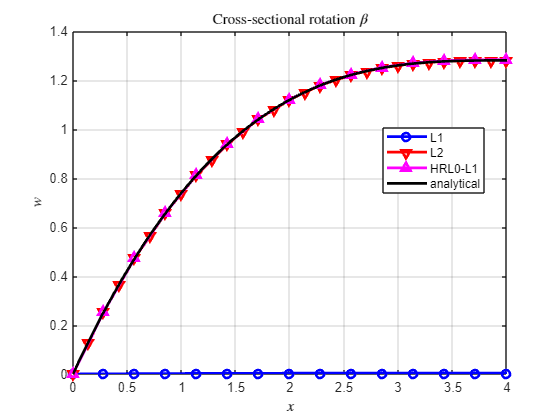

figure,
plot(mshL1.nodes, uL1(2:2:end, 1), '-bo', LineWidth=2);
hold on;
plot(nodes_L2, betaL2Sorted, '-rv', LineWidth=2);
plot(nodesHR, betaHR, '-m^', LineWidth=2);
fplot(betaEx, [X0 XL], 'k-', LineWidth=2);
hold off;
grid on;
legend("L1", "L2", "HR" + strHR, "analytical", Location="best")
xlabel("$x$", Interpreter="latex");
ylabel("$w$", Interpreter="latex");
title("Cross-sectional rotation $\beta$", Interpreter="latex")

 **Reflect**

How does the solution of the Hellinger-Reissner formulation compare against the analytical solution for different combinations of discretizations for the primal unknown fields (vertical deflection and cross-sectional rotation fields) and the secondary unknown fields (Lagrange Multipliers fields for the unknown reaction force and reaction moment fields)?

## Weak enforcement of the kinematics condition

In this section it is demonstrated the effect on applying the kinematics condition weakly via the Hellinger-Reissner principle. Strong enforcement of the kinematics conditions $\gamma = \frac{\partial w}{\partial X} + \beta$ and $\kappa = \frac{\partial \beta}{ \partial X}$ implies that $\frac{1}{\alpha GA} Q = \frac{\partial w}{\partial X} + \beta$ and $\frac{1}{EI} M = \frac{\partial \beta}{ \partial X}$, respectively, since the constitutive law is strongly enforced. In this section it is demonstrated the left-hand sides of the latter equations, namely, $\frac{1}{\alpha GA} Q $ and $\frac{1}{EI} M$, are not exactly equal to the right-hand sides of these equations, namely, $ \frac{\partial w}{\partial X} + \beta$ and $\frac{\partial \beta}{ \partial X}$, respectively. The demonstration is confined only in the shear part of the stiffness, namely, the terms $\frac{1}{\alpha GA} Q $ and $ \frac{\partial w}{\partial X} + \beta$.

### Initialization of the auxiliary variables

syms posVctHR(xi) wHR(xi) betaHR(xi) dwdxHR(xi) gammaHR(xi) gammaHR_compl(xi)

Number of evaluation points

numPts = 50;

Evaluation points

boundingBox = [min(mshHR.nodes(:, 1)) max(mshHR.nodes(:, 1))];
XVctHR = linspace(boundingBox(1), boundingBox(2), numPts);

Initialize figure

figure,

### Loop over all evaluation points

for ii = 1:numPts

#### **Find the element to which the evaluation point belongs**    

    if ii ~= 1
        elprev = el;
    end
    el = nan;
    for jj = 1:numel(mshHR.elements(:, 1))

Set up the position vector regarding the discretization of the primal fields using the Hellinger-Reissner formulation

        posVctHR(xi) = NuHR*mshHR.nodes(mshHR.elements(jj, :));

Construct the inverse position vector corresponding to the current element $\xi(x) = x(\xi)^{-1}$

        posVctHRInv = finverse(posVctHR);

Compute the parametric coordinate of the evaluation point in the current element using the element's inverse parametric representation

        xiParamHR = posVctHRInv(XVctHR(ii));

Check whether the computed parametric coordinate $\xi$ is within the closed space $[-1,1]$. If it is, then the evaluation point belongs to the current element, otherwise not

        if xiParamHR >= -1 && xiParamHR <= 1
            el = jj;
            break;
        end

    end

#### Verification of the element's validity containing the current point

    if isnan(el)
        error("The point with coordinate %d was found " + ...
            "in no element in the mesh", x(ii));
    end

#### Set-up the Element Freedom Table (EFT) for the one-dimensional linear element

    EFTHR = [2*mshHR.elements(el, :) - 1; 2*mshHR.elements(el, :)];
    EFTHR = EFTHR(:);

#### Setup of the expressions for the vertical deflection and rotation fields for the one-dimensional linear element

    wHR(xi) = NuHR*uHR(EFTHR(1:2:end), 1); % w(x)
    betaHR(xi) = NuHR*uHR(EFTHR(2:2:end), 1); % β(x)

#### Computation of the derivatives of the vertical deflection and rotation fields with respect to the physical space

To compute the derivatives of the basis functions with respect to the physical space given that they are defined in the parametric space, the chain rule in one-dimensiona can be used, namely:


$$\frac{\text{d} w}{\text{d} x} = \frac{\text{d} w}{\text{d} \xi} \overbrace{\frac{\text{d} \xi}{\text{d} x}}^{J^{-1}}$$


The inverse of the Jacobian matrix for the one-dimensional elements is given by the following expression:


$$J^{-1}(\xi) = \frac{\text{d} \xi}{\text{d} x}$$


i.e. it is simply a scalar quantity. The Jacobian matrix in this case can be computed using function [`jacobian`](https://www.mathworks.com/help/symbolic/sym.jacobian.html) in MATLAB:

    jacobianMtxHR = jacobian(posVctHR, xi);

Setting-up the derivatives of the vertical deflection field corresponding to the one-dimensional linear elements based on full integration with respect to the physical space

    dwdxHR(xi) = transpose(inv(jacobianMtxHR(xi)))*diff(wHR, xi);

Compute the transverse-shear strain $\gamma(\xi) = \frac{\text{d} w (\xi)}{\text{d} x} + \beta(\xi)$ at the evaluation point

    gammaHR(xi) = dwdxHR(xi) + betaHR(xi);

Primal solution $\left( u^e,\beta^e \right)$ - Lagrange Multipliers $\left( Q^e, M^e \right)$ coupling matrix $\mathbf{G}^e$ of the element where the evaluation point belongs to

    if ii == 1 || el ~= elprev
        [~, ~, Ge] = computeElStiffMtxForceVctHellingerReissnerTimoshenkoBeam ...
            (NuHR, Nbeta, mshHR.nodes(mshHR.elements(el, :), :), propStr);
    end

Siscrete solution of the Lagrange Multipliers $\left( Q^e, M^e \right)$ using the primal solution $\left( u^e,\beta^e \right)$ at the evaluation point

    QhatHR = Ge(1, 1:2:end)*uHR(EFTHR(1:2:end), 1);
    MhatHR = Ge(2, 2:2:end)*uHR(EFTHR(2:2:end), 1);

Strain using the interpolation of the Lagrange Mutipliers solution

    gammaHR_compl(xi) = 1/(propStr.alpha*propStr.G*propStr.A)*Nbeta*QhatHR;

Figure of transverse-shear strain vs the kinematics condition

    fplot({gammaHR, gammaHR_compl}, [-1, 1], LineWidth=2)
    legend("$\frac{d w (\xi)}{d x} + \beta(\xi)$", "$\frac{1}{\alpha G A} Q$", ...
        Interpreter='latex', location='best')
    mytitleText = "Difference between terms $\frac{d w (\xi)}{d x} + \beta(\xi)$ " + ...
        "and $\frac{1}{\alpha G A} Q$ at element " + num2str(el);
    title(mytitleText, Interpreter="latex")
    xlabel("$\xi$", Interpreter="latex")
    ylabel("$\frac{d w (\xi)}{d x} + \beta(\xi)$, $\frac{1}{\alpha G A} Q$", Interpreter="latex")
    drawnow;

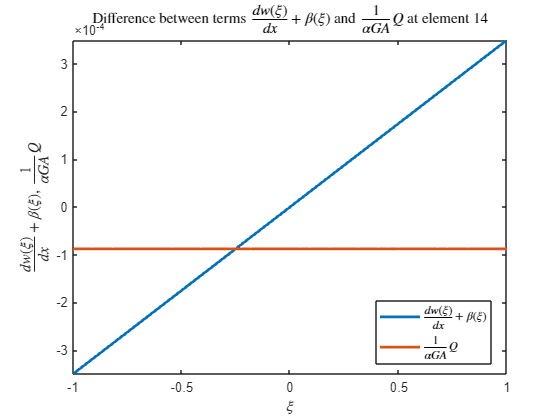

end

  **Try**

Plot the bending strain $\frac{1}{EI} M$ against the change in the curvature $\frac{\partial \beta}{ \partial X}$ . You can adapt the code above in this section to enable this comparison.

 **Reflect**

- Is the kinematics condition in what concerns the bending part of the energy also applied weakly into the system via the Hellinger-Reissner principle?

- Is it necessary to apply the kinematics condition of the bending part of the energy weakly into the system to eliminate transverse-shear locking in the case of the Timoshenko beam problem?

## References

[[1] Koschnick, Frank. *Geometrische Locking-Effekte bei finiten Elementen und ein allgemeines Konzept zu ihrer Vermeidung*. Diss. München, Techn. Univ., Diss., 2004.](https://mediatum.ub.tum.de/doc/601060/0000003e.pdf)

## **Helper functions**

### **Element Stiffness Matrix and body force vector**

function [Ke, Fe, Ge] = ...
    computeElStiffMtxForceVctHellingerReissnerTimoshenkoBeam ...
    (Nu, Nbeta, nodesEl, propStr)

**Function description**

Returns the element stiffness matrix for an element based on the Hellinger-Reissner formulation of the 1D Timoshenko theory with four degrees of freedom per node $\left(w,\beta ,Q,M\right)$, the vertical deflection, the rotation of the beam's cross section around the X-axis, the reaction transverse shear forces and the reaction bending moments, respectively, using full integration. The pair of unknowns for the secondary unknown fields $\left(Q,M\right)$ is condensed out from the equation system. Assuming that the vector of DOFs related to the primal unknown fields $\left(w,\beta \right)$ is denoted as $\mathbf{u}$ whereas the vector of DOFs associated with the secondary unknown fields $\left(Q,M\right)$ is denoted by $\mathbf{\beta}$, the discrete equation system regarding the Hellinger-Reissner formulation of the Timoshenko beam problem reads as follows:


$$\left[ \begin{array}{cc} - \mathbf{H} & \mathbf{G} \\ 
\mathbf{G}^{\text{T}} & \mathbf{0} \end{array}\right] \left[ \begin{array}{c} \mathbf{\beta} \\ \mathbf{u} \end{array} \right] = \left[ \begin{array}{c} \mathbf{0} \\ \mathbf{F} \end{array} \right]$$


where,

$\mathbf{H}^e = \int_{e} \mathbf{N}_{\mathbf{\beta}}^{\text{T}} \, \mathbf{S} \, \mathbf{N}_{\mathbf{\beta}} \; \text{d} e$,

$\mathbf{G}^e = \int_{e} \mathbf{N
}_{\mathbf{\beta}}^{\text{T}} \, \mathbf{B}_{\mathbf{\mathbf{u}}} \; \text{d} e$.

B-operator matrix $\mathbf{B}_{\mathbf{\beta}}$ is related to the discretization of the pair $\left(Q,M\right)$ and it is given by the following equation,

$\mathbf{N}_{\mathbf{\beta}} = \left[ \begin{array}{ccccc} N_1^{\mathbf{\beta}} & 0 & \ldots & N_{n_{\mathbf{\beta}}}^{\mathbf{\beta}} & 0 \\ 
0 & N_1^{\mathbf{\beta}} & \ldots & 0 & N_{n_{\mathbf{\beta}}}^{\mathbf{\beta}}\end{array} \right]$,

since derivatives on the secondary pair of unknown fields do not appear, also piecewise constant functions can be used as basis functions. B-operator matrix $\mathbf{B}_{\mathbf{u}}$ is related to the discretization of the shear deformation $\gamma = \frac{\text{d} w}{\text{d} x} + \beta$ and it has been introduced already in the standard variational formulation of the Timoshenko beam. Finally, the compliance matrix $\mathbf{S}$ is given by the following relationship,

$\mathbf{S} = \left[ \begin{array}{cc} \frac{1}{\alpha G A} & 0 \\ 0 & \frac{1}{EI} \end{array} \right]$, which is basically the inverse of the material matrix in this case.

**           Input :**

                `Nu` : Vector containing the symbolic expression for the basis functions regarding the pair of unknown fields $\left( w, \beta\right)$

          `Nbeta` : Vector containing the symbolic expression for the basis functions regarding the pair of unknown fields $\left( Q, M \right)$

      `nodesEl` : Nodal coordinates of the finite element arranged in a column-vector

      `propStr` : Structure containing the following fields,

                              `.A` : Cross sectional area of the beam

                              `.q` : Distributed load on the beam

                              `.m` : Distributed moment on the beam

                              `.E` : Young's modulus

                            `.nu` : Poisson's ratio

                              `.I` : Moment of inertia

                              `.G` : Shear modulus

                      `.alpha` : Shear correction factor

**       Output :**

               `Ke` : Element stiffness matrix of a Timoshenko beam

               `Fe` : Element force vector of the Timoshenko beam

               `Ge` : Element coupling matrix $\mathbf{G}^e = \int_{L^e} \mathbf{N}_\beta \mathbf{B}_u \: \text{d}L^e$

**Function implementation**

#### Read-input

if numel(nodesEl) ~= numel(Nu(0))
    error("The number of nodes %d do not match the number " + ...
        "of basis functions %d", numel(nodesEl), numel(Nu(0)))
end

#### Set-up the geometric map $x(\xi) = \sum_{i=1}^n N_i(\xi) x_i$:

syms xi
numNodesuEl = numel(Nu(xi));
numNodesbetaEl = numel(Nbeta(xi));
xel = sym('xel', [numNodesuEl 1]);
x = Nu*xel;

#### Get the polynomial order of the element

pEl = numNodesuEl - 1;

#### Get the number of DOFs per element

numDOFsuEl = 2*numNodesuEl;
numDOFsbetaEl = 2*numNodesbetaEl;

#### Set-up the Jacobian $J(\xi) = \frac{\text{d} x(\xi)}{\text{d} \xi} = \sum_{i = 1}^n \frac{\text{d} N_i(\xi)}{\text{d} \xi}x_i$:

J = jacobian(x, xi);

#### Transform the derivatives of the basis functions from the parametric to the physical space


$$\frac{\text{d} N_i (\xi)}{\text{d} x} = \frac{\text{d} N_i (\xi)}{\text{d} \xi} \frac{\text{d} \xi}{\text{d} x} = \frac{\text{d} N_i (\xi)}{\text{d} \xi} J^{-1}$$
  

syms dN(xi)
dN(xi) = J\diff(Nu, xi);

#### Computation of the material matrix

syms alphaScf G A E I
S = [1/(alphaScf*G*A) 0
     0                 1/(E*I)];

#### Symbolic formulation of the basis function matrix

Nmtx = sym(zeros(2, numDOFsuEl));
for ii = 1:numNodesuEl
    filtermtx = zeros(numNodesuEl, 1);
    filtermtx(ii) = 1;
    Nmtx(1, 2*ii - 1) = Nu*filtermtx;
    Nmtx(2, 2*ii) = Nu*filtermtx;
end

#### Set-up the B-Operator matrix for the pair vertical deflections - cross sectional rotations symbolically

Bumtx = sym(zeros(2, numDOFsuEl));
for ii = 1:numNodesuEl
    filtermtx = zeros(numNodesuEl, 1);
    filtermtx(ii) = 1;
    Bumtx(1, 2*ii - 1) = dN*filtermtx;
    Bumtx(1, 2*ii) = Nu*filtermtx;
    Bumtx(2, 2*ii) = dN*filtermtx;
end

#### Formulation of the B-operator matrix for the pair shear forces - bending moments

Nbetamtx = sym(zeros(2, numDOFsbetaEl));
for ii = 1:numNodesbetaEl
    filtermtx = zeros(numNodesbetaEl, 1);
    filtermtx(ii) = 1;
    Nbetamtx(1, 2*ii - 1) = Nbeta*filtermtx;
    Nbetamtx(2, 2*ii) = Nbeta*filtermtx;
end

#### Set up element stiffness matrix and load vector integrands

syms q m HeIntegrand(xi) GeIntegrand(xi) FeIntegrand(xi)
HeIntegrand(xi) = transpose(Nbetamtx)*S*Nbetamtx;
GeIntegrand(xi) = transpose(Nbetamtx)*Bumtx;
FeIntegrand(xi) = transpose(Nmtx)*[q; m];

#### Choose method for computing the element stiffness matrix

integrationMethod = 2;
if integrationMethod == - 1
    if numNodesuEl == 2
        method = 1;
    elseif numNodesuEl == 3
        method = 2;
    else
        method = 2;
    end
else
    method = integrationMethod;
end

#### Compute the symbolic expression of the element stiffness matrix and load vector based on the selected method

switch method

*1.) Method 1: Perform the variable substitution *$\xi =\xi \left(X\right)$ which is the inverse of map $X=X\left(\xi \right)$:

    case 0


$$B\left(\xi \right)=B\left(\xi \left(X\right)\right)=\bar{B} \left(X\right),$$



$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dx}=\int_{X_1 }^{X_2 } {\bar{B} }^T \left(x\right)C\bar{B} \left(x\right)\;\textrm{dx}$$



$$\int_{X_1 }^{X_2 } N^T \left(\xi \right)p\left(\xi \right)\;\textrm{dx}=\int_{X_1 }^{X_2 } {\bar{N} }^T \left(x\right)\bar{p} \left(x\right)\;\textrm{dx}$$


        syms X
        Xxi = solve(X == x(xi), xi);
        HeIntBar = subs(HeIntegrand, xi, Xxi);
        GeIntBar = subs(GeIntegrand, xi, Xxi);
        FeIntBar = subs(FeIntegrand, xi, Xxi);
        HeInt = int(HeIntBar, X, nodesEl(1), nodesEl(2));
        GeInt = int(GeIntBar, X, nodesEl(1), nodesEl(2));
        FeInt = int(FeIntBar, X, nodesEl(1), nodesEl(2));

*2.) Method 2: Transform the element stiffness matrix in the element's parent space [-1 , 1]:*

    case 1


$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dX}=\int_{-1}^{+1} B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi$$



$$\int_{X_1 }^{X_2 } N\left(\xi \right)p\left(\xi \right)\;\textrm{dX}=\int_{-1}^{+1} N\left(\xi \right)p\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi$$


Symbolic computation of the element stiffness matrix

        HeInt = int(HeIntegrand*det(J), xi, -1, 1);
        GeInt = int(GeIntegrand*det(J), xi, -1, 1);
        FeInt = int(FeIntegrand*det(J), xi, -1, 1);

*3.) Method 3: Transform the element stiffness matrix in the element's parent space [-1 , 1] and perform Gaussian integration*

    case 2


$$\int_{X_1 }^{X_2 } B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} B^T \left(\xi \right)\textrm{CB}\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^2 B^T \left(\xi_i \right)\textrm{CB}\left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$



$$\int_{X_1 }^{X_2 } N\left(\xi \right)p\left(\xi \right)\;\textrm{dx}=\int_{-1}^{+1} N\left(\xi \right)p\left(\xi \right)\;\det \left(J\left(\xi \right)\right)\;d\xi =\sum_{i=1}^2 N\left(\xi_i \right)p\left(\xi_i \right)\;\det \left(J\left(\xi_i \right)\right)w_i$$


Symbolic computation of the element stiffness matrix

        numGP = pEl + 1;
        [xiGP, GW_xi] = getGaussPointsAndWeightsOverUnitDomain(numGP);
        HeInt = sym(zeros(numDOFsbetaEl));
        GeInt = sym(zeros(numDOFsbetaEl, numDOFsuEl));
        FeInt = sym(zeros(numDOFsuEl, 1));
        for ii = 1:height(GW_xi)
            HeInt = HeInt + HeIntegrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
            GeInt = GeInt + GeIntegrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
            FeInt = FeInt + FeIntegrand(xiGP(ii))*det(J(xiGP(ii)))*GW_xi(ii);
        end

Assert an error in case neither of cases 0, 1, 2 or 3 is chosen:

    otherwise
        error("Variable 'method' should take the values 0, 1, 2 or 3 " + ...
            "but it has instead the value %d\n", method);
end

#### Numerical evaluation of the element stiffness matrix and load vector

He = subs(HeInt, [alphaScf, G, E, A, I, transpose(xel)], ...
    [propStr.alpha, propStr.G, propStr.E, propStr.A, ...
    propStr.I, transpose(nodesEl)]);
Ge = subs(GeInt, transpose(xel), transpose(nodesEl));
Fe = subs(FeInt, [q, m, transpose(xel)], ...
    [propStr.qBar, propStr.mBar, transpose(nodesEl)]);

#### Compute the part of the stiffness matrix associated purely with the vertical deflection - cross sectional rotation DOFs

Ke = transpose(Ge)*(He\Ge); % Simplification for the expression transpose(Ge)*inv(He)*Ge

end